% 필요한 데이터 불러오기
params_tbl = readtable('LHS 파라미터(csv).csv');


== [w_h: 0.9, w_c: 0.1] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 9.12


Reb_F Level      = 4.80


Comp_R Level     = 7.08


Reb_R Level      = 8.68


Handling Score   = 1.0404


Comfort Score    = 0.9169


Total Score      = 1.0280


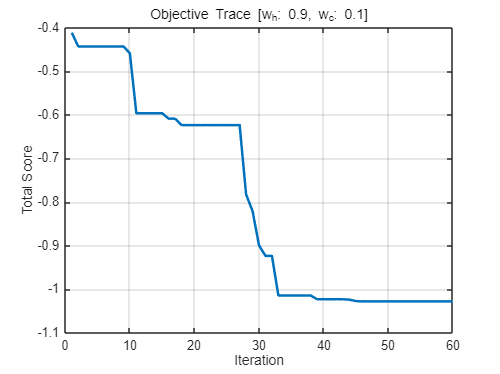


== [w_h: 0.8, w_c: 0.2] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 9.56


Reb_F Level      = 6.99


Comp_R Level     = 7.28


Reb_R Level      = 10.93


Handling Score   = 1.0243


Comfort Score    = 0.9114


Total Score      = 1.0017


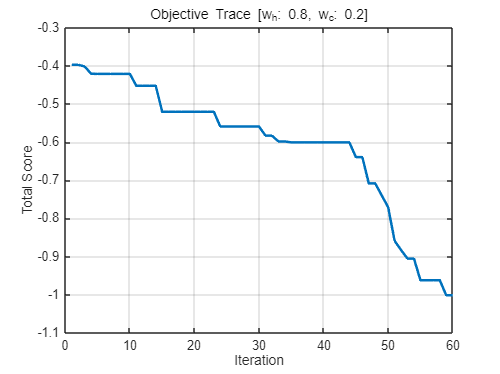


== [w_h: 0.7, w_c: 0.3] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 11.66


Reb_F Level      = 6.39


Comp_R Level     = 7.02


Reb_R Level      = 9.66


Handling Score   = 1.0311


Comfort Score    = 0.9987


Total Score      = 1.0214


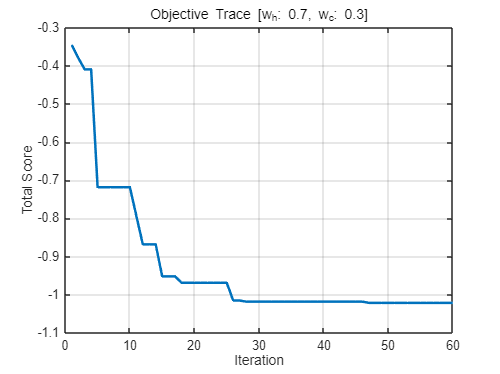


== [w_h: 0.6, w_c: 0.4] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 1.16


Reb_F Level      = 5.92


Comp_R Level     = 6.97


Reb_R Level      = 9.69


Handling Score   = 1.0330


Comfort Score    = 1.0020


Total Score      = 1.0206


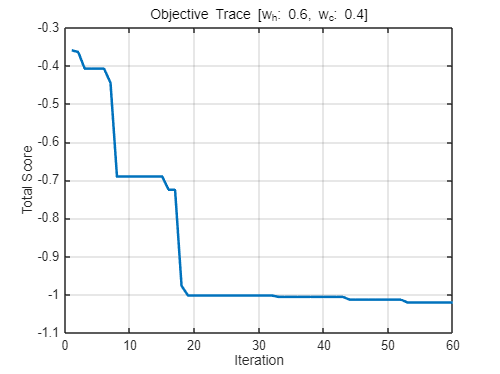


== [w_h: 0.5, w_c: 0.5] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 10.40


Reb_F Level      = 5.43


Comp_R Level     = 6.80


Reb_R Level      = 10.10


Handling Score   = 1.0338


Comfort Score    = 0.9912


Total Score      = 1.0125


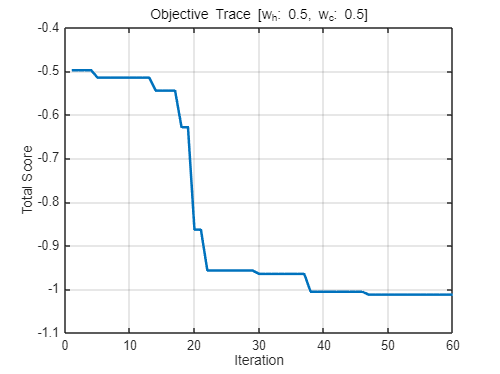


== [w_h: 0.4, w_c: 0.6] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 2.33


Reb_F Level      = 4.40


Comp_R Level     = 7.27


Reb_R Level      = 9.35


Handling Score   = 1.0386


Comfort Score    = 0.9387


Total Score      = 0.9786


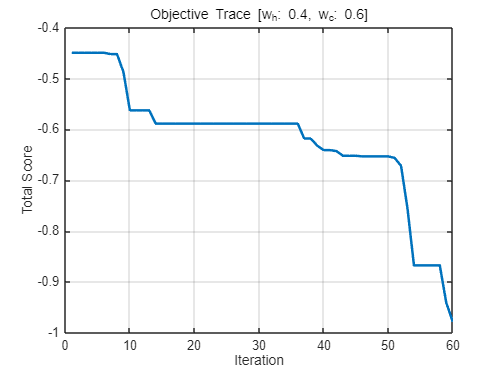


== [w_h: 0.3, w_c: 0.7] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 8.29


Reb_F Level      = 6.14


Comp_R Level     = 7.36


Reb_R Level      = 9.99


Handling Score   = 1.0304


Comfort Score    = 0.9995


Total Score      = 1.0088


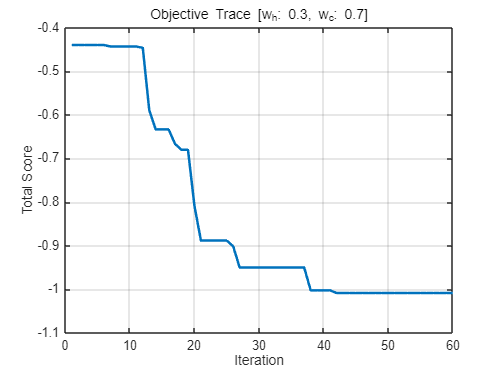


== [w_h: 0.2, w_c: 0.8] 최적 설계 ==


Spring Level     = 3.99


Comp_F Level     = 7.85


Reb_F Level      = 6.23


Comp_R Level     = 7.26


Reb_R Level      = 9.77


Handling Score   = 1.0252


Comfort Score    = 1.0010


Total Score      = 1.0059


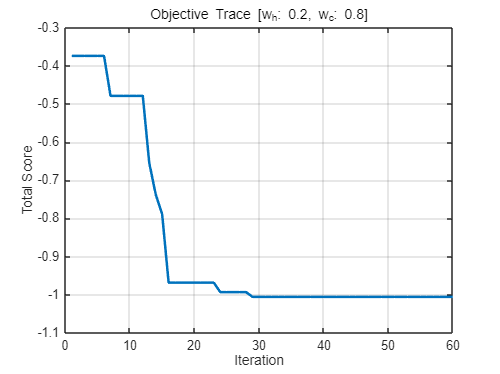


== [w_h: 0.1, w_c: 0.9] 최적 설계 ==


Spring Level     = 4.00


Comp_F Level     = 1.95


Reb_F Level      = 6.06


Comp_R Level     = 6.42


Reb_R Level      = 9.80


Handling Score   = 1.0193


Comfort Score    = 1.0022


Total Score      = 1.0040


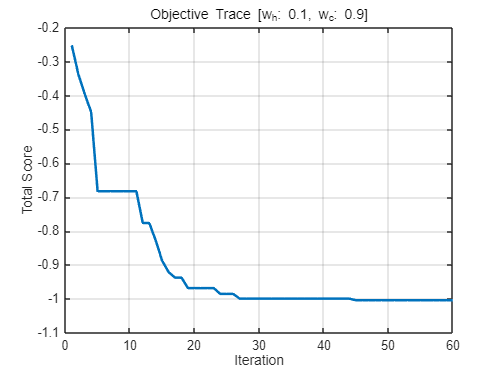

load('Vib_Data.mat');  % T_all 포함

% GPR 입력 & 출력 정의
X_train = [params_tbl.Spring, params_tbl.Comp_F, params_tbl.Reb_F, params_tbl.Comp_R, params_tbl.Reb_R];

roll_angle_rms = T_all.RollAngle_RMS_deg;
lat_acc_rms     = T_all.RMS_LateralAcc_ms2;
heave_rms       = T_all.RMS_HeaveAcc_ms2;
pitch_acc_rms   = T_all.Pitch_Acc_RMS_degps2;
roll_acc_rms    = T_all.Roll_Acc_RMS_degps2;
psd_rms         = T_all.Heave_PSD_RMS_mps2;

% 정규화 (작을수록 좋음)
normalize = @(x) (x - min(x)) / (max(x) - min(x));
roll_norm   = normalize(roll_angle_rms);
lat_norm    = normalize(lat_acc_rms);
pitch_norm  = normalize(pitch_acc_rms);
rolla_norm  = normalize(roll_acc_rms);
heave_norm  = normalize(heave_rms);
psd_norm    = normalize(psd_rms);

Handling_Score = 0.5 * (1 - roll_norm) + 0.5 * (1 - lat_norm);
Comfort_Score  = 0.3 * (1 - heave_norm) + 0.3 * (1 - psd_norm) + ...
                 0.2 * (1 - pitch_norm) + 0.2 * (1 - rolla_norm);

% GPR 모델 학습
gprModel_handling = fitrgp(X_train, Handling_Score, 'KernelFunction','ardsquaredexponential','Standardize',true);
gprModel_comfort  = fitrgp(X_train, Comfort_Score,  'KernelFunction','ardsquaredexponential','Standardize',true);
% gprModel_handling = fitrgp(X_train, Handling_Score, 'KernelFunction','matern52','Standardize',true);
% gprModel_comfort  = fitrgp(X_train, Comfort_Score,  'KernelFunction','matern52','Standardize',true);

% 최적화 대상 변수 정의
vars = [
    optimizableVariable('Spring',[1,4])
    optimizableVariable('Comp_F',[1,12])
    optimizableVariable('Reb_F',[1,22])
    optimizableVariable('Comp_R',[1,12])
    optimizableVariable('Reb_R',[1,22])
];

% 결과 테이블 초기화
results_tbl = table();

% 가중치 반복 (Handling:Comfort = 1:0 ~ 0:1)
for i = 0:10
    w_h = (10 - i)/10;
    w_c = i/10;

    % 1:0 또는 0:1은 제외
    if w_h == 1 || w_c == 1
        continue;
    end

    % 목적함수 정의 (부호 반전: 최대화 → 최소화 문제로 변환)
    objfun = @(x) -(w_h * predict(gprModel_handling, table2array(x)) + ...
                    w_c * predict(gprModel_comfort,  table2array(x)));

    % Bayesian Optimization
    results = bayesopt(objfun, vars, ...
        'MaxObjectiveEvaluations', 60, ...
        'IsObjectiveDeterministic', true, ...
        'Verbose', 0, ...
        'PlotFcn', {@plotAcquisitionFunction});

    best = bestPoint(results);
    best_arr = table2array(best);
    
    % 예측값
    H = predict(gprModel_handling, best_arr);
    C = predict(gprModel_comfort, best_arr);
    T = w_h * H + w_c * C;

    % 결과 출력
    fprintf('\n== [w_h: %.1f, w_c: %.1f] 최적 설계 ==\n', w_h, w_c);
    fprintf('Spring Level     = %.2f\n', best_arr(1));
    fprintf('Comp_F Level     = %.2f\n', best_arr(2));
    fprintf('Reb_F Level      = %.2f\n', best_arr(3));
    fprintf('Comp_R Level     = %.2f\n', best_arr(4));
    fprintf('Reb_R Level      = %.2f\n', best_arr(5));
    fprintf('Handling Score   = %.4f\n', H);
    fprintf('Comfort Score    = %.4f\n', C);
    fprintf('Total Score      = %.4f\n', T);

    % Figure 저장
    figure;
    plot(results.ObjectiveMinimumTrace, 'LineWidth', 2);
    title(sprintf('Objective Trace [w_h: %.1f, w_c: %.1f]', w_h, w_c));
    xlabel('Iteration');
    ylabel('Total Score');
    grid on;

    % 결과 테이블 저장
    results_tbl = [results_tbl; table(w_h, w_c, ...
        best_arr(1), best_arr(2), best_arr(3), best_arr(4), best_arr(5), ...
        H, C, T, ...
        'VariableNames', {
            'w_h', 'w_c', ...
            'Spring', 'Comp_F', 'Reb_F', 'Comp_R', 'Reb_R', ...
            'Handling_Score', 'Comfort_Score', 'Total_Score'
        })];
end


% 전체 결과 출력
disp(results_tbl);

    w_h    w_c    Spring    Comp_F    Reb_F     Comp_R    Reb_R     Handling_Score    Comfort_Score    Total_Score
    ___    ___    ______    ______    ______    ______    ______    ______________    _____________    ___________

    0.9    0.1    3.9982     9.115    4.8008    7.0758    8.6838        1.0404           0.91688           1.028  
    0.8    0.2    3.9986    9.5589    6.9866    7.2828    10.927        1.0243           0.91135          1.0017  
    0.7    0.3     3.998    11.661    6.3916    7.0189    9.6588        1.0311           0.99874          1.0214  
    0.6    0.4    3.9965    1.1571    5.9156    6.9682    9.6864         1.033             1.002          1.0206  
    0.5    0.5    3.9961    10.399    5.4283    6.7982    10.101        1.0338           0.99123          1.0125  
    0.4    0.6    3.9973    2.3308    4.3967    7.2721    9.3509        1.0386           0.93866         0.97864  
    0.3    0.7    3.9995    8.2889    6.1391    7.3553    9.9852        1.0304 


% 엑셀로 저장 (원할 경우 주석 해제)
% writetable(results_tbl, 'BayesOpt_Result_Summary.xlsx');

% ==== 기준 파라미터 성능 계산 ====
baseline_params = [2.5, 6.5, 11.5, 6.5, 11.5];  % Spring, Comp_F, Reb_F, Comp_R, Reb_R
H_baseline = predict(gprModel_handling, baseline_params);
C_baseline = predict(gprModel_comfort, baseline_params);
T_baseline = 0.5 * H_baseline + 0.5 * C_baseline;

% ==== 0.5 : 0.5 최적 파라미터 성능 가져오기 ====
row_5050 = results_tbl(results_tbl.w_h == 0.5 & results_tbl.w_c == 0.5, :);
T_opt = row_5050.Total_Score;
improvement = T_opt - T_baseline;

% ==== 출력 ====
fprintf('\n[Baseline 중간값 파라미터 성능 비교]\n');


[Baseline 중간값 파라미터 성능 비교]


fprintf('Handling Score   = %.4f\n', H_baseline);

Handling Score   = 0.4085


fprintf('Comfort Score    = %.4f\n', C_baseline);

Comfort Score    = 0.3463


fprintf('Total Score      = %.4f\n', T_baseline);

Total Score      = 0.3774



fprintf('\n[BayesOpt 최적 (0.5:0.5) 대비 개선량]\n');


[BayesOpt 최적 (0.5:0.5) 대비 개선량]


fprintf('개선된 Total Score = %.4f → %.4f (Δ = %.4f)\n', ...
    T_baseline, T_opt, improvement);

개선된 Total Score = 0.3774 → 1.0125 (Δ = 0.6351)



% ==== 개선율(%) 계산 ====
H_opt = row_5050.Handling_Score;
C_opt = row_5050.Comfort_Score;

H_improve_pct = (H_opt - H_baseline) / H_baseline * 100;
C_improve_pct = (C_opt - C_baseline) / C_baseline * 100;
T_improve_pct = (T_opt - T_baseline) / T_baseline * 100;

% ==== 출력 ====
fprintf('\n[Baseline 중간값 파라미터 성능 비교]\n');


[Baseline 중간값 파라미터 성능 비교]


fprintf('Handling Score   = %.4f\n', H_baseline);

Handling Score   = 0.4085


fprintf('Comfort Score    = %.4f\n', C_baseline);

Comfort Score    = 0.3463


fprintf('Total Score      = %.4f\n', T_baseline);

Total Score      = 0.3774



fprintf('\n[BayesOpt 최적 (0.5:0.5) 대비 개선률]\n');


[BayesOpt 최적 (0.5:0.5) 대비 개선률]


fprintf('Handling Score 개선: %.2f%%\n', H_improve_pct);

Handling Score 개선: 153.08%


fprintf('Comfort Score 개선: %.2f%%\n', C_improve_pct);

Comfort Score 개선: 186.27%


fprintf('Total Score 개선: %.2f%%\n', T_improve_pct);

Total Score 개선: 168.31%



%%%%%%%%%%%%%%%%%%% 상대적 중요도 분석 %%%%%%%%%%%%%
% ==== 파라미터 중요도 분석 (Handling 기준) ====
kernelParams_handling = gprModel_handling.KernelInformation.KernelParameters;
lengthScales_handling = kernelParams_handling(1:end-1);  % 마지막은 Signal Std Dev

importance_handling = 1 ./ lengthScales_handling;
importance_handling = importance_handling / sum(importance_handling);  % 정규화

fprintf('\n[Handling GPR 파라미터 중요도 (Normalized)]\n');


[Handling GPR 파라미터 중요도 (Normalized)]


param_names = {'Spring', 'Comp_F', 'Reb_F', 'Comp_R', 'Reb_R'};
for i = 1:length(param_names)
    fprintf('%s 중요도: %.4f\n', param_names{i}, importance_handling(i));
end

Spring 중요도: 0.9542
Comp_F 중요도: 0.0000
Reb_F 중요도: 0.0128
Comp_R 중요도: 0.0330
Reb_R 중요도: 0.0000



% ==== Comfort 기준도 동일하게 수행 가능 ====
kernelParams_comfort = gprModel_comfort.KernelInformation.KernelParameters;
lengthScales_comfort = kernelParams_comfort(1:end-1);

importance_comfort = 1 ./ lengthScales_comfort;
importance_comfort = importance_comfort / sum(importance_comfort);

fprintf('\n[Comfort GPR 파라미터 중요도 (Normalized)]\n');


[Comfort GPR 파라미터 중요도 (Normalized)]


for i = 1:length(param_names)
    fprintf('%s 중요도: %.4f\n', param_names{i}, importance_comfort(i));
end

Spring 중요도: 0.2388
Comp_F 중요도: 0.0000
Reb_F 중요도: 0.2970
Comp_R 중요도: 0.0000
Reb_R 중요도: 0.4642


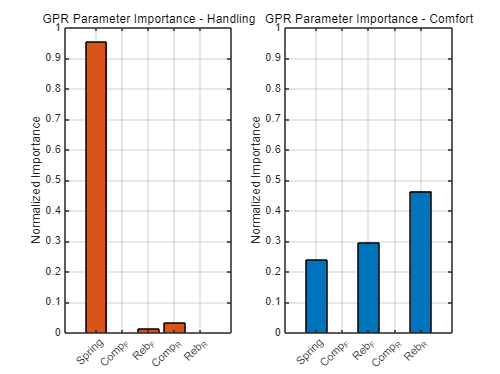



%% === 파라미터 중요도 시각화 ===

param_names = {'Spring', 'Comp_F', 'Reb_F', 'Comp_R', 'Reb_R'};

figure;

% Handling 중요도 시각화
subplot(1,2,1);
bar(importance_handling, 'FaceColor', [0.85 0.33 0.10]);  % Red-orange
set(gca, 'XTickLabel', param_names, 'XTickLabelRotation', 45);
ylabel('Normalized Importance');
title('GPR Parameter Importance - Handling');
ylim([0 1]);
grid on;

% Comfort 중요도 시각화
subplot(1,2,2);
bar(importance_comfort, 'FaceColor', [0.00 0.45 0.74]);  % Blue
set(gca, 'XTickLabel', param_names, 'XTickLabelRotation', 45);
ylabel('Normalized Importance');
title('GPR Parameter Importance - Comfort');
ylim([0 1]);
grid on;

%% === K-Fold Cross-Validation 기반 GPR 성능 평가 ===

k = 5;  % fold 수 설정
cv = cvpartition(size(X_train,1), 'KFold', k);

% 결과 저장용
rmse_handling_all = zeros(k,1);
r2_handling_all   = zeros(k,1);
rmse_comfort_all  = zeros(k,1);
r2_comfort_all    = zeros(k,1);

fprintf('\n=== %d-Fold GPR Cross-Validation ===\n', k);


=== 5-Fold GPR Cross-Validation ===



for i = 1:k
    fprintf('\n--- Fold %d ---\n', i);
    
    % 학습/검증 분할
    train_idx = training(cv, i);
    test_idx  = test(cv, i);
    
    X_tr = X_train(train_idx,:);
    X_te = X_train(test_idx,:);
    
    H_tr = Handling_Score(train_idx);
    H_te = Handling_Score(test_idx);
    
    C_tr = Comfort_Score(train_idx);
    C_te = Comfort_Score(test_idx);
    
    % GPR 모델 학습
    gpr_h = fitrgp(X_tr, H_tr, 'KernelFunction','ardsquaredexponential','Standardize',true);
    gpr_c = fitrgp(X_tr, C_tr, 'KernelFunction','ardsquaredexponential','Standardize',true);
    
    % 예측
    H_pred = predict(gpr_h, X_te);
    C_pred = predict(gpr_c, X_te);
    
    % 성능 계산
    rmse = @(y, yhat) sqrt(mean((y - yhat).^2));
    r2   = @(y, yhat) 1 - sum((y - yhat).^2) / sum((y - mean(y)).^2);
    
    rmse_handling_all(i) = rmse(H_te, H_pred);
    r2_handling_all(i)   = r2(H_te, H_pred);
    
    rmse_comfort_all(i)  = rmse(C_te, C_pred);
    r2_comfort_all(i)    = r2(C_te, C_pred);
    
    % 디버그용 출력
    fprintf('Handling - RMSE: %.4f, R²: %.4f\n', rmse_handling_all(i), r2_handling_all(i));
    fprintf('Comfort  - RMSE: %.4f, R²: %.4f\n', rmse_comfort_all(i),  r2_comfort_all(i));
end


--- Fold 1 ---


Handling - RMSE: 0.2774, R²: -1.1039


Comfort  - RMSE: 0.2670, R²: -6.4956



--- Fold 2 ---


Handling - RMSE: 0.2144, R²: -0.0725


Comfort  - RMSE: 0.2292, R²: -0.1612



--- Fold 3 ---


Handling - RMSE: 0.0927, R²: -0.5134


Comfort  - RMSE: 0.1959, R²: -0.3157



--- Fold 4 ---


Handling - RMSE: 0.2240, R²: 0.3706


Comfort  - RMSE: 0.4287, R²: -1.1256



--- Fold 5 ---


Handling - RMSE: 0.0716, R²: 0.1956


Comfort  - RMSE: 0.0553, R²: -0.5043



% 평균 성능 출력
fprintf('\n=== 평균 성능 (Across %d folds) ===\n', k);


=== 평균 성능 (Across 5 folds) ===


fprintf('[Handling Score] RMSE: %.4f | R²: %.4f\n', mean(rmse_handling_all), mean(r2_handling_all));

[Handling Score] RMSE: 0.1760 | R²: -0.2247


fprintf('[Comfort Score]  RMSE: %.4f | R²: %.4f\n', mean(rmse_comfort_all),  mean(r2_comfort_all));

[Comfort Score]  RMSE: 0.2352 | R²: -1.7205


%% Pareto 기반 최적 설계를 위한 샘플 설계 공간 생성
N_samples = 1000000;
X_sampled = lhsdesign(N_samples, 5);  % [0~1] 범위 샘플 생성
X_sampled(:,1) = 1 + 3 * X_sampled(:,1);   % Spring: [1,4]
X_sampled(:,2) = 1 + 11 * X_sampled(:,2);  % Comp_F: [1,12]
X_sampled(:,3) = 1 + 21 * X_sampled(:,3);  % Reb_F:  [1,22]
X_sampled(:,4) = 1 + 11 * X_sampled(:,4);  % Comp_R: [1,12]
X_sampled(:,5) = 1 + 21 * X_sampled(:,5);  % Reb_R:  [1,22]

% 예측
H_pred = predict(gprModel_handling, X_sampled);
C_pred = predict(gprModel_comfort,  X_sampled);

% Pareto front 계산 (최대화 → 부호 반전)
pareto_flags = paretofront([-H_pred, -C_pred]);

% 시각화 및 최적 탐색
w_range = 0.1:0.1:0.9;
colors = jet(length(w_range));
legend_entries = {};

figure; hold on; grid on;
xlabel('Handling Score'); ylabel('Comfort Score');
title('Pareto Optimal Designs');

% Pareto 점 시각화
scatter(H_pred(pareto_flags), C_pred(pareto_flags), 20, [0.5 0.5 0.5], 'filled');

for i = 1:length(w_range)
    w_h = w_range(i);
    w_c = 1 - w_h;

    total_score = w_h * H_pred + w_c * C_pred;

    % Pareto 내부에서 최적 Total Score 찾기
    pareto_idx = find(pareto_flags);
    [~, best_local_idx] = max(total_score(pareto_idx));
    best_idx = pareto_idx(best_local_idx);

    % 최적점 정보 출력
    fprintf('\n== Pareto 기반 최적 설계 (Handling:Comfort = %.1f:%.1f) ==\n', w_h, w_c);
    fprintf('Spring   = %.2f\n', X_sampled(best_idx,1));
    fprintf('Comp_F   = %.2f\n', X_sampled(best_idx,2));
    fprintf('Reb_F    = %.2f\n', X_sampled(best_idx,3));
    fprintf('Comp_R   = %.2f\n', X_sampled(best_idx,4));
    fprintf('Reb_R    = %.2f\n', X_sampled(best_idx,5));
    fprintf('Handling Score = %.4f\n', H_pred(best_idx));
    fprintf('Comfort Score  = %.4f\n', C_pred(best_idx));
    fprintf('Total Score    = %.4f\n', total_score(best_idx));

    % 그래프 표시
    scatter(H_pred(best_idx), C_pred(best_idx), 60, colors(i,:), 'filled');
    legend_entries{end+1} = sprintf('w_h: %.1f, w_c: %.1f', w_h, w_c);
end


== Pareto 기반 최적 설계 (Handling:Comfort = 0.1:0.9) ==


Spring   = 3.99


Comp_F   = 7.45


Reb_F    = 5.82


Comp_R   = 7.21


Reb_R    = 9.80


Handling Score = 1.0207


Comfort Score  = 1.0015


Total Score    = 1.0034



== Pareto 기반 최적 설계 (Handling:Comfort = 0.2:0.8) ==


Spring   = 3.99


Comp_F   = 7.45


Reb_F    = 5.82


Comp_R   = 7.21


Reb_R    = 9.80


Handling Score = 1.0207


Comfort Score  = 1.0015


Total Score    = 1.0053



== Pareto 기반 최적 설계 (Handling:Comfort = 0.3:0.7) ==


Spring   = 3.99


Comp_F   = 7.45


Reb_F    = 5.82


Comp_R   = 7.21


Reb_R    = 9.80


Handling Score = 1.0207


Comfort Score  = 1.0015


Total Score    = 1.0072



== Pareto 기반 최적 설계 (Handling:Comfort = 0.4:0.6) ==


Spring   = 3.99


Comp_F   = 7.45


Reb_F    = 5.82


Comp_R   = 7.21


Reb_R    = 9.80


Handling Score = 1.0207


Comfort Score  = 1.0015


Total Score    = 1.0092



== Pareto 기반 최적 설계 (Handling:Comfort = 0.5:0.5) ==


Spring   = 3.99


Comp_F   = 7.45


Reb_F    = 5.82


Comp_R   = 7.21


Reb_R    = 9.80


Handling Score = 1.0207


Comfort Score  = 1.0015


Total Score    = 1.0111



== Pareto 기반 최적 설계 (Handling:Comfort = 0.6:0.4) ==


Spring   = 3.99


Comp_F   = 7.45


Reb_F    = 5.82


Comp_R   = 7.21


Reb_R    = 9.80


Handling Score = 1.0207


Comfort Score  = 1.0015


Total Score    = 1.0130



== Pareto 기반 최적 설계 (Handling:Comfort = 0.7:0.3) ==


Spring   = 3.99


Comp_F   = 7.45


Reb_F    = 5.82


Comp_R   = 7.21


Reb_R    = 9.80


Handling Score = 1.0207


Comfort Score  = 1.0015


Total Score    = 1.0149



== Pareto 기반 최적 설계 (Handling:Comfort = 0.8:0.2) ==


Spring   = 4.00


Comp_F   = 6.27


Reb_F    = 5.27


Comp_R   = 6.71


Reb_R    = 8.86


Handling Score = 1.0352


Comfort Score  = 0.9518


Total Score    = 1.0185



== Pareto 기반 최적 설계 (Handling:Comfort = 0.9:0.1) ==


Spring   = 4.00


Comp_F   = 6.27


Reb_F    = 5.27


Comp_R   = 6.71


Reb_R    = 8.86


Handling Score = 1.0352


Comfort Score  = 0.9518


Total Score    = 1.0269


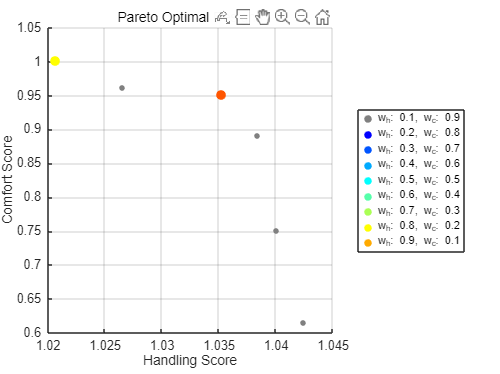


legend(legend_entries, 'Location', 'eastoutside');